
% Run the Simulink model (assuming your model is named 'HW1simulink3')
sim('HW1simulink3');
Bacillus = out.Bacillus

Bacillus = 1.0e+07 *

    0.0010
    0.0011
    0.0011
    0.0012
    0.0012
    0.0013
    0.0014
    0.0014
    0.0015
    0.0016


Staphylococcus = out.Staphylococcus

Staphylococcus = 1.0e+09 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


bacteriophage = out.bacteriophage

bacteriophage = 1.0e+07 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


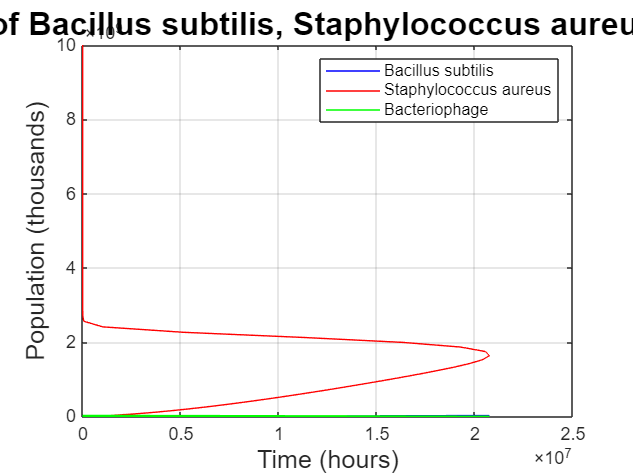

% Retrieve logged data from the workspace
b_data = evalin('base', 'Bacillus'); % Bacillus subtilis population
s_data = evalin('base', 'Staphylococcus'); % Staphylococcus aureus population
p_data = evalin('base', 'bacteriophage'); % Bacteriophage population

% Extract time and data for each variable
time = b_data(:, 1);          % Time vector
b_values = b_data(:, 1);      % Population of Bacillus subtilis
s_values = s_data(:, 1);      % Population of Staphylococcus aureus
p_values = p_data(:, 1);      % Population of bacteriophage

% Plot the population growth of Bacillus subtilis, Staphylococcus aureus, and bacteriophage
figure;
plot(time, b_values, 'b', time, s_values, 'r', time, p_values, 'g');
title('Population Growth of Bacillus subtilis, Staphylococcus aureus, and Bacteriophage', 'FontSize', 18);
xlabel('Time (hours)', 'FontSize', 14);
ylabel('Population (thousands)', 'FontSize', 14);
legend('Bacillus subtilis', 'Staphylococcus aureus', 'Bacteriophage');
grid on;